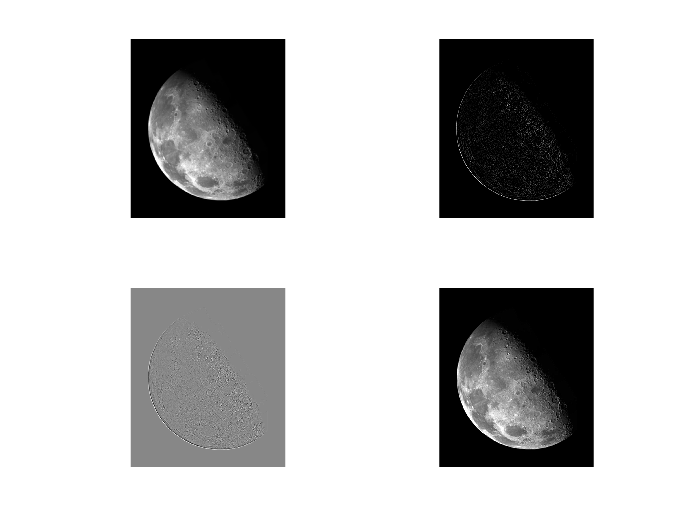

clear;clc;

f=imread("Fig0217(a).tif");
figure;
subplot(2,2,1);
imshow(f);
w=fspecial('laplacian',0);%拉普拉斯滤波器
g1=imfilter(f,w,'replicate');%使用nuit8格式的拉普拉斯滤波后的图像，因为unit8为无符号类型，所以输出的负值剪切为0
subplot(2,2,2);
imshow(g1,[]);
f2=tofloat(f);%将f转化为浮点型数据
g2=imfilter(f2,w,'replicate');%使用浮点型的图像进行拉普拉斯滤波
subplot(2,2,3);
imshow(g2,[]);
g=f2-g2;%增强图像，在原图像中减去中心为-4的滤波结果
subplot(2,2,4);
imshow(g);